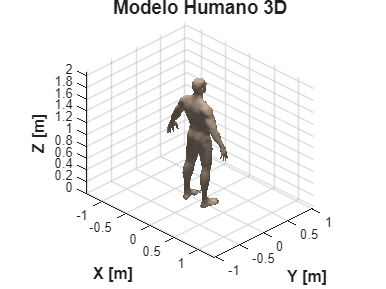

close all; clear all; clc

% Leer archivo STL
TR = stlread('human_mesh/FinalBaseMesh.stl');

% Matriz de rotación en X
Rxy = rotx(90)*roty(180);

% Aplicar rotación a los puntos
rotatedPoints = (Rxy * (TR.Points)')'*(1/10);

% Crear nueva triangulación con puntos rotados
TR = triangulation(TR.ConnectivityList, rotatedPoints);

% Crear figura
figure('Color', 'w', 'Position', [100, 100, 1200, 900]);
hold on; grid on; axis equal;

% Dibujar el modelo humano
patch('Faces', TR.ConnectivityList, 'Vertices', TR.Points, ...
      'FaceColor', [0.85 0.75 0.65], ...  % Color piel
      'EdgeColor', 'none', ...
      'FaceAlpha', 0.8);

% Configurar iluminación
lighting gouraud;
camlight('headlight');
material dull;

% Configurar ejes
xlabel('X [m]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Y [m]', 'FontSize', 12, 'FontWeight', 'bold');
zlabel('Z [m]', 'FontSize', 12, 'FontWeight', 'bold');
title('Modelo Humano 3D', 'FontSize', 14, 'FontWeight', 'bold');

% Vista
view(45, 30);
rotate3d on;

hold off;